# ANMA: Introduction to interpolation and approximation

This MATLAB notebook presents a practical demonstration of the mathematics from Lecture 6.

Make sure you understand how the code in this workbook implements the corresponding mathematics.

**Tasks:**

- Compare the polynomial and RBF methods for square systems. Which has the lower error, why? How do the interpolating curves differ between the two methods?

- Vary the number of input data points and determine a rule for choosing a good RBF support radius

- Extra: try changing the RBF definition to use a different radial function (see Lecture 7 part 2)

**Tip:** right-click in the plotting pane (on the right) and select 'Disable Synchronous Scrolling' to more-easily work with this notebook.

*Laurence Kedward 2021, University of Bristol*

*laurence.kedward@bristol.ac.uk*

## Define our discrete data

This is the set of data points that we wish to fit a continuous function to. Here we are just generating a random sequence.

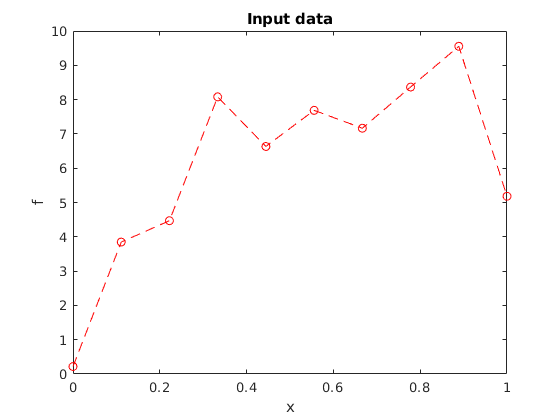

clear variables;
% Number of data points
N = 10;

x_data = linspace(0,1,N)';           % x locations of data points
f_data = cumsum(2*randn([N,1]));   % f values of data points (random)

plot(x_data,f_data,'ro--');  % Plot our random data
title('Input data');xlabel('x');ylabel('f');

## Define our basis

Try changing these parameters to see how the approximation varies.

Note that the RBF basis is always square (interpolating) because we define our basis functions to be centered on our input data points.

% Interpolation basis type
basis = "rbf";

% Number of polynomial terms
%  (polynomial basis only)
M_poly = 3;

% RBF support radius
%   (rbf basis only)
SR = 0.4;

## Construct our basis

Here we construct the matrices required to fit and evaluate our continuous approximation.

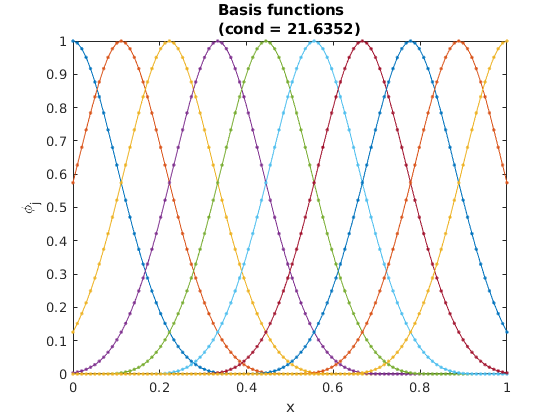

% Number of fine grid points to plot continuous function
N_fine = 100;

% Number of basis functions to use
if strcmp(basis,'polynomial')
    M = M_poly;
elseif strcmp(basis,'rbf')
    M = N;
end %if

% Function for Euclidian distance normalised by support radius
r = @(dx) sqrt(sum(dx.*dx,2))/SR;

% Define our rbf function (Wendland's C2)
rbf = @(dx) (r(dx)<=1).*((1-r(dx)).^4).*(4*r(dx)+1);

% Define a fine grid for evaluating the continuous approximation
x_fine = linspace(0,1,N_fine)';

% Our linear basis matrix
A = zeros(N,M);

% Our fine grid evaluation matrix
B = zeros(N_fine,M);

% Fill our basis matrix and evaluation matrix one column at a time
for j=1:M
    
    % The jth column is the jth basis function evaluated at the x locations
    
    if strcmp(basis,'polynomial')
        
        A(:,j) = x_data.^(j-1);
        B(:,j) = x_fine.^(j-1);
        
        
    elseif strcmp(basis,'rbf')
        
        A(:,j) = rbf(x_data-x_data(j));
        B(:,j) = rbf(x_fine-x_data(j));
        
    end
    
end

% Plot our basis functions using the fine grid
plot(x_fine,B,'.-');
title(['Basis functions\newline(cond = ',num2str(cond(A),'%G'),')']);
xlabel('x');ylabel('\phi_j');

## Fit our data using the basis

We use the MATLAB backslash \ operator to solve the linear system for our weights

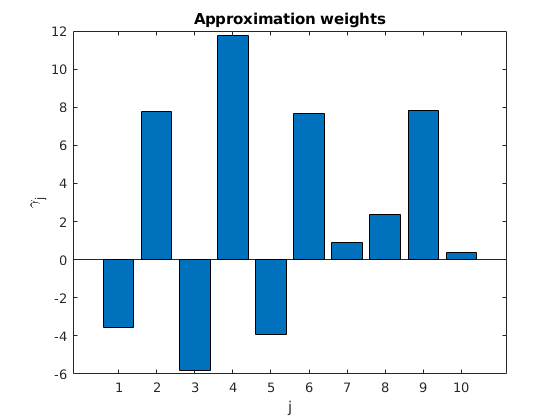

% Perform matrix inverse / least squares fitting
gamma = A\f_data;

% Plot our gamma weights
bar(gamma);
title('Approximation weights');xlabel('j');ylabel('\gamma_j');

## Plot our approximation function

Once we have our weights we can evaluate the continuous function on a fine grid using matrix B

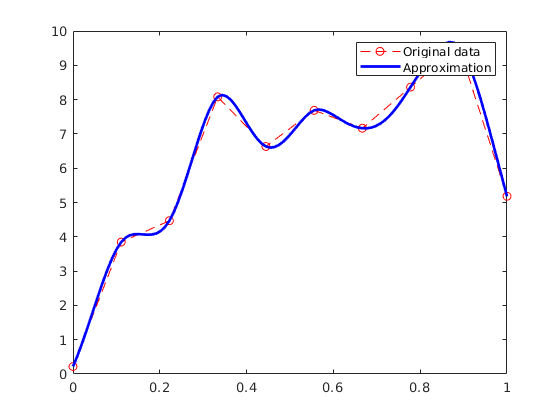

% Perform the weighted summation
f_fine = B*gamma;

% Plot the approximation using the fine grid
plot(x_data,f_data,'ro--'); hold on;
plot(x_fine,f_fine,'Color','Blue','LineWidth',2.0);hold off;
legend('Original data','Approximation');

## Plot the approximation error at the data points

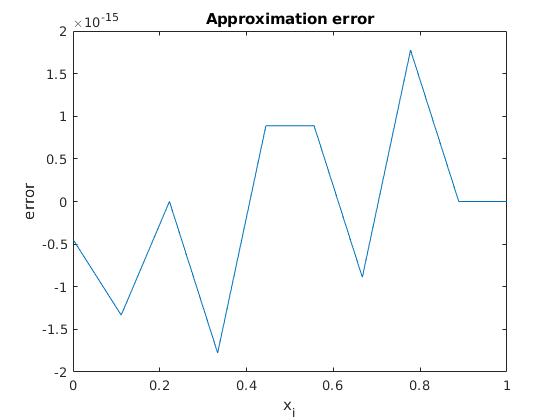

e = f_data - A*gamma;
plot(x_data,e);
title('Approximation error');xlabel('x_i');ylabel('error');